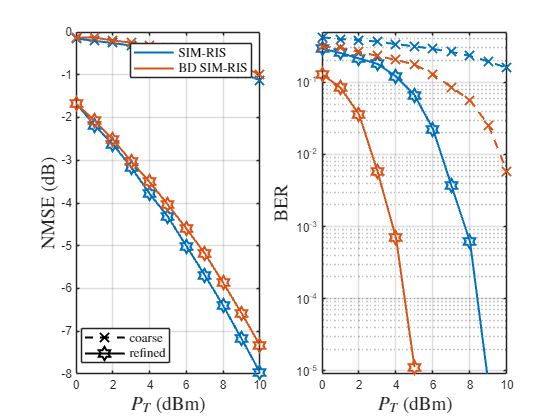

%load data
clear
load("MAIN_SIM_5_layers.mat")

% BER PLOT =====================================================================================================
subplot(1,2,1);

% coarse
NMSE = pow2db(NmseVec(1,:));
plot(Pw_user_dBm,NMSE,'Color','#0072BD','LineStyle','-','LineWidth',1.5,'Marker',"x",'MarkerSize',10);
hold on
% \nu = 1
NMSE = pow2db(NmseVec(2,:));
plot(Pw_user_dBm,NMSE,'Color','#0072BD','LineStyle','-','LineWidth',1.5,'Marker',"hexagram",'MarkerSize',10);
% % Peformance Limit
% NMSE = pow2db(NmseVec(3,:));
% plot(Pw_user_dBm,NMSE,'Color','#0072BD','LineStyle','--','LineWidth',1.5,'Marker',"o",'MarkerSize',10);

clear
load("MAIN_BD_5_layer.mat")

% coarse
NMSE = pow2db(NmseVec(1,:));
plot(Pw_user_dBm,NMSE,'Color','#D95319','LineStyle','-','LineWidth',1.5,'Marker',"x",'MarkerSize',10);

% \nu = 1
NMSE = pow2db(NmseVec(2,:));
plot(Pw_user_dBm,NMSE,'Color','#D95319','LineStyle','-','LineWidth',1.5,'Marker',"hexagram",'MarkerSize',10);

% % Peformance Limit
% NMSE = pow2db(NmseVec(3,:));
% plot(Pw_user_dBm,NMSE,'Color','#D95319','LineStyle','--','LineWidth',1.5,'Marker',"o",'MarkerSize',10);

% ------------------------------------------------------------------------------------------------------
% axis labels
xlabel('$P_T$ (dBm)','Interpreter','latex','FontSize',14);
ylabel('NMSE (dB)','Interpreter','latex','FontSize',14);
subplot(1,2,1)
% ylim([10^-5 0.5]);
xlim([0 10]);
xticks(0:2:10)
% legend('Initial','$\nu = 1$','$\nu = 2$','$\nu = 3$','benchmark','Interpreter','latex')
grid on

% legend(["Initial", "$\rho=1$", "$\rho=2$", "$\rho=3$", "$\rho=4$", "$\rho=5$", "Benchmark"], "Position", [0.13682,0.11005,0.20357,0.28333],'Interpreter','latex','FontSize',10)
% % BER Plot========================================================================================================

Ax1=axes('Position',get(gca,'Position'),'Visible','Off');
xlim([1 2])
hold on
Plotdummy0(1) = plot(Ax1,0,0,'Color','#0072BD','LineStyle','-','LineWidth',1.5,'MarkerSize',10);
Plotdummy0(2) = plot(Ax1,0,0,'Color','#D95319','LineStyle','-','LineWidth',1.5,'MarkerSize',10);
legend(Ax1,Plotdummy0(:),{'SIM-RIS';'BD SIM-RIS'},'Interpreter','latex','FontSize',10);

Ax3=axes('Position',get(gca,'Position'),'Visible','Off');
hold on
xlim([1 2])
Plotdummy2(1) = plot(Ax3,0,0,'Color','k','LineStyle','--','LineWidth',1.5,'Marker',"x",'MarkerSize',10);
Plotdummy2(2) = plot(Ax3,0,0,'Color','k','LineStyle','-','LineWidth',1.5,'Marker',"hexagram",'MarkerSize',10);
legend(Ax3,Plotdummy2(:),{'coarse';'refined'}, 'Location','SouthWest','Interpreter','latex','FontSize',10);




clear
load("MAIN_SIM_5_layers.mat")

% BER PLOT =====================================================================================================
subplot(1,2,2);

% Initial
BER = (BerVec(1,:));
semilogy(Pw_user_dBm,BER,'Color','#0072BD','LineStyle','--','LineWidth',1.5,'Marker',"x",'MarkerSize',10);
hold on
% \nu = 1
BER = (BerVec(2,:));
semilogy(Pw_user_dBm,BER,'Color','#0072BD','LineStyle','-','LineWidth',1.5,'Marker',"hexagram",'MarkerSize',10);

clear
load("MAIN_BD_5_layer.mat")

% \nu =  2
BER = (BerVec(1,:));
semilogy(Pw_user_dBm,BER,'Color','#D95319','LineStyle','--','LineWidth',1.5,'Marker',"x",'MarkerSize',10);

%"IDD W/O RiS Perfect CSI (3)";
BER = (BerVec(2,:));
BER(7)=0;
semilogy(Pw_user_dBm,BER,'Color','#D95319','LineStyle','-','LineWidth',1.5,'Marker',"hexagram",'MarkerSize',10);

% ------------------------------------------------------------------------------------------------------
% axis labels
xlabel('$P_T$ (dBm)','Interpreter','latex','FontSize',14);
ylabel('BER','Interpreter','latex','FontSize',14);
ylim([9*10^-6 0.5]);
xlim([0 10]);
xticks(0:2:10)
% legend('Initial','$\nu = 1$','$\nu = 2$','$\nu = 3$','benchmark','Interpreter','latex','FontSize',10)
grid on